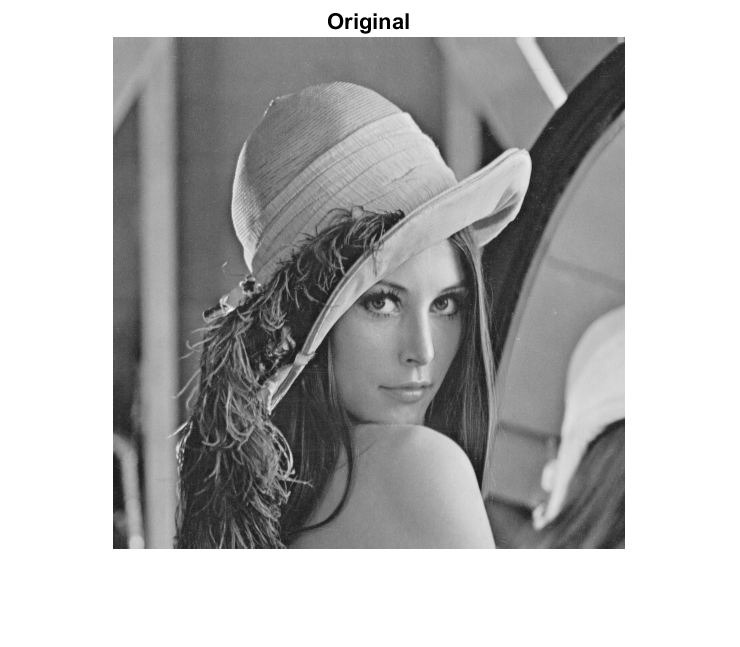

clear 
close all

img = im2double(imread('BM3D_images/Lena512.png'));

% define a blurring filter
h = fspecial('motion',30,40);

% define the image size
[Mi,Ni] = size(img);
[Mh,Nh] = size(h);
M = Mi + Mh - 1;
N = Ni + Nh - 1;

% corrupt the image
sigma_noise = 5/255;
% corrupt the image
z = conv2(img,h,'full') + sigma_noise*randn(M, N);

% show the corrupted and the original image
figure, imshow(img), title('Original')

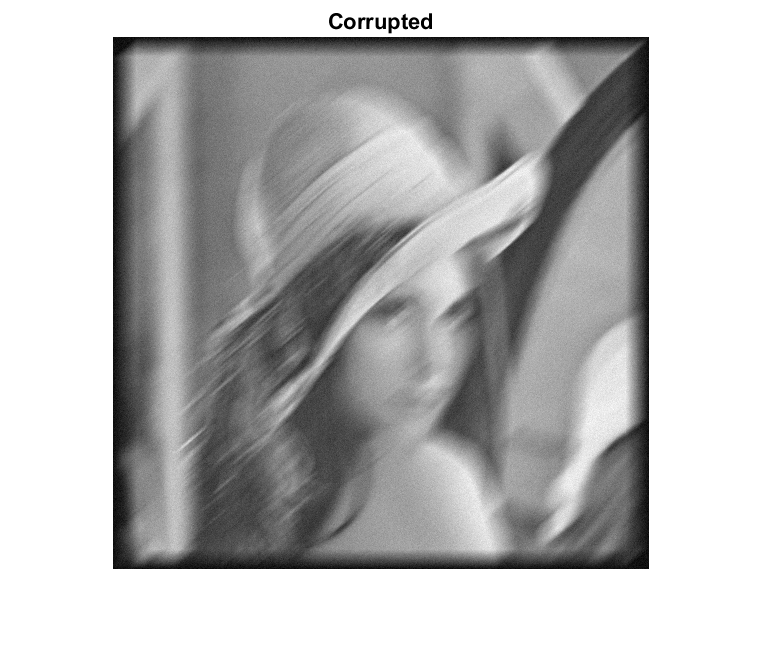

figure, imshow(z,[]), title('Corrupted')



% compute the fourier transform of the noisy image with padding
z_f = fft2(z,M,N);
% compute the fourier transform of the blurring filter with padding
h_f = fft2(h,M,N);

## apply the ideal wiener filter

compute the fourier transform of the original image

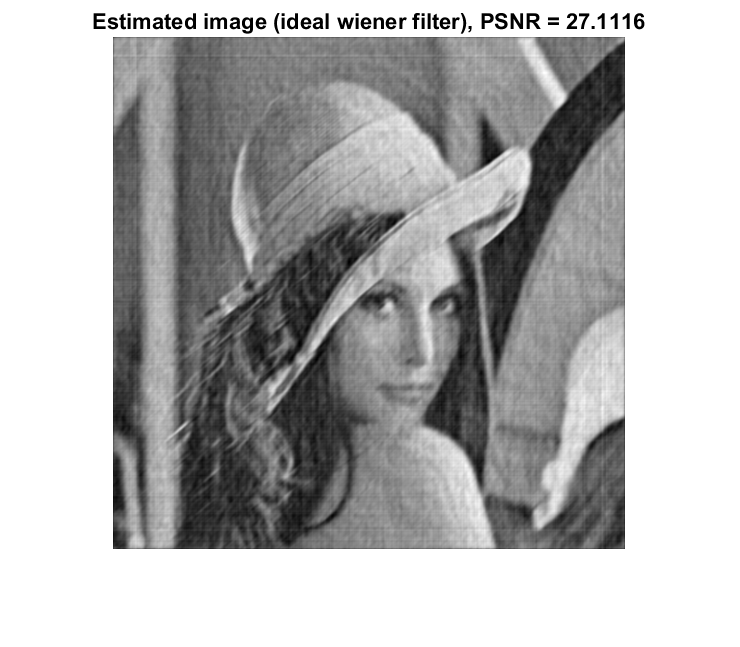

img_f = fft2(img, M, N);
% set the PSD as the fourier transform of the previously estimated image
PSD = abs(img_f);

% compute the fourier transform of estimated image using the Wiener filtering
img_hat_f = 1 ./ h_f .* abs(h_f).^2 ./(abs(h_f).^2 + M*N*sigma_noise^2./PSD.^2) .* z_f;

% invert the fourier transform
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_ideal = 10*log10(1/mean((img_hat(:) - img(:)).^2));

% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (ideal wiener filter), PSNR = ', num2str(psnr_ideal)]);

## use the cameraman image to estimate the PSD

load the cameraman image to estimate the PSD

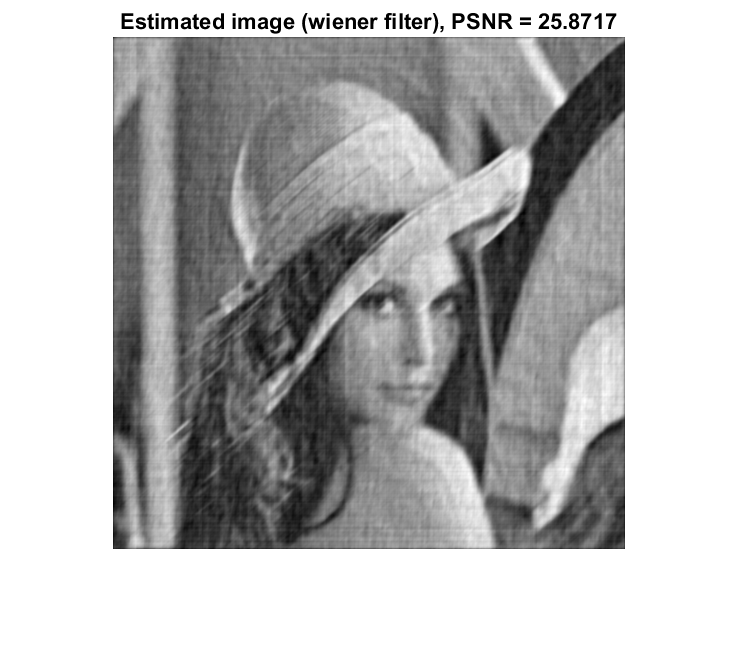

img2 = im2double(imread('BM3D_images/Cameraman256.png'));
img2_f = fft2(img2, M, N);
PSD = abs(img2_f);


% compute the fourier transform of estimated image using the Wiener filtering
img_hat_f = 1 ./ h_f .* abs(h_f).^2 ./(abs(h_f).^2 + M*N*sigma_noise^2./PSD.^2) .* z_f;

% invert the fourier transform
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_wiener = 10*log10(1/mean((img_hat(:) - img(:)).^2));

% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (wiener filter), PSNR = ', num2str(psnr_wiener)]);

## apply the wiener filter another time

set the PSD as the fourier transform of the previously estimated image

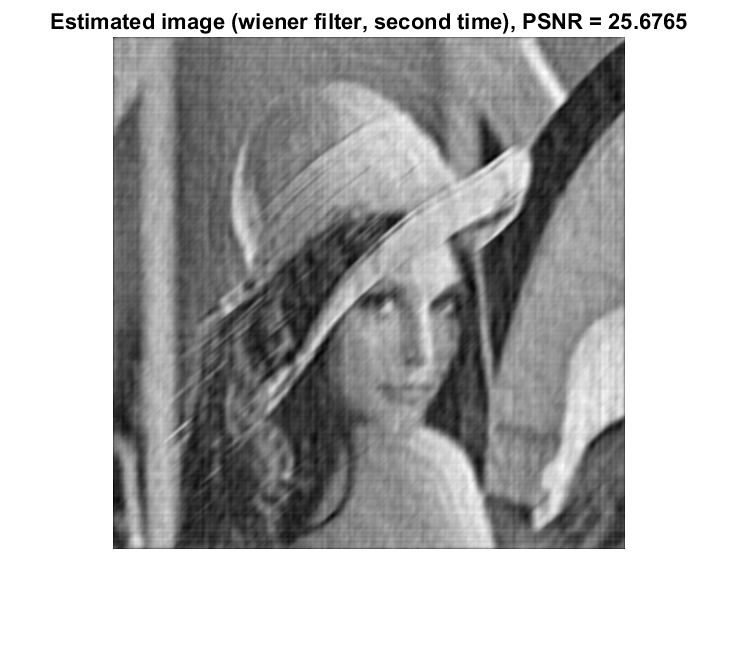

PSD = abs(img_hat_f);

% compute the fourier transform of estimated image using the Wiener filtering
img_hat_f = 1 ./ h_f .* abs(h_f).^2 ./(abs(h_f).^2 + M*N*sigma_noise^2./PSD.^2) .* z_f;

% invert the fourier transform
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_wiener2 = 10*log10(1/mean((img_hat(:) - img(:)).^2));

% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (wiener filter, second time), PSNR = ', num2str(psnr_wiener2)]);